clear all
close all

% GRAPH/DIGRAPH #1/2
Gx=[0 2*cos(pi/6) -2*cos(pi/6) 0];  % position x
Gy=[2 -2*0.5 -2*0.5 0]; % position y

X_l = [ 0 0.15 0.3 0.45 0.6 0.75 0.9 1.05 1.2; 0 0.05 0.1 0.15 0.2 0.25 0.3 0.35 0.4 ]

X_l =          0    0.1500    0.3000    0.4500    0.6000    0.7500    0.9000    1.0500    1.2000
         0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000


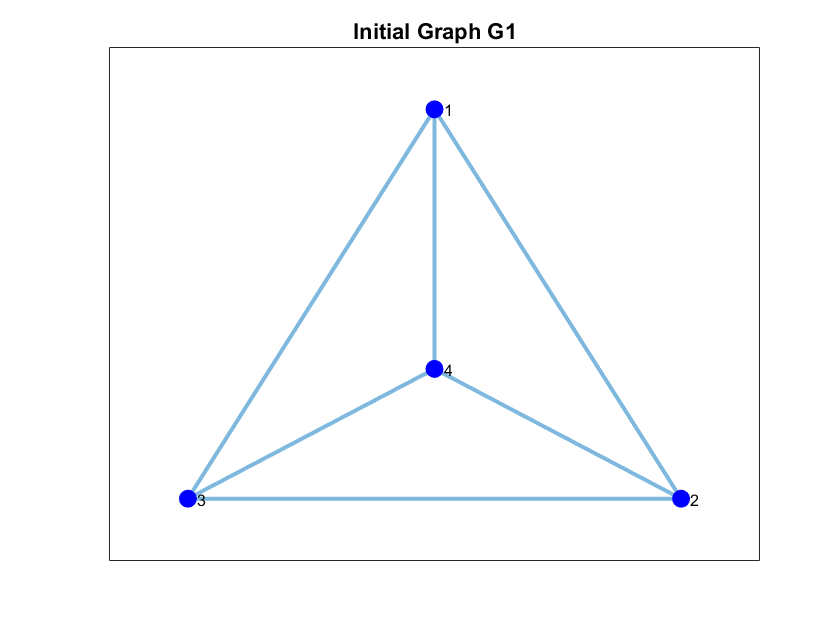

% GRAPH #1
edgesG1 = [ 1 2;
            1 3;
            1 4;
            2 4;
            2 3;
            3 4];
figure; G1 = graph(edgesG1(:,1),edgesG1(:,2));
plot(G1,'XData',Gx,'YData',Gy,'MarkerSize',8,'NodeColor','b', 'LineWidth',2);
xticks([]); yticks([]); title('Initial Graph G1')


% Adjacency matrix
A = [   0 1 1 1;   
        1 0 1 1;   
        1 1 0 1;   
        1 1 1 0];  

% Degree matrix
D = diag([3 3 3 3]);

% Laplacian matrix
L = D-A

L =      3    -1    -1    -1
    -1     3    -1    -1
    -1    -1     3    -1
    -1    -1    -1     3


% CASE 1 
%P = eye(4);
P = [0 1/2 1/2 0;
    1/2 0 1/2 0;
    1/2 1/2 0 0;
    0 0 0 1]

P =          0    0.5000    0.5000         0
    0.5000         0    0.5000         0
    0.5000    0.5000         0         0
         0         0         0    1.0000


sigmaP = eig(P)

sigmaP =    -0.5000
   -0.5000
    1.0000
    1.0000


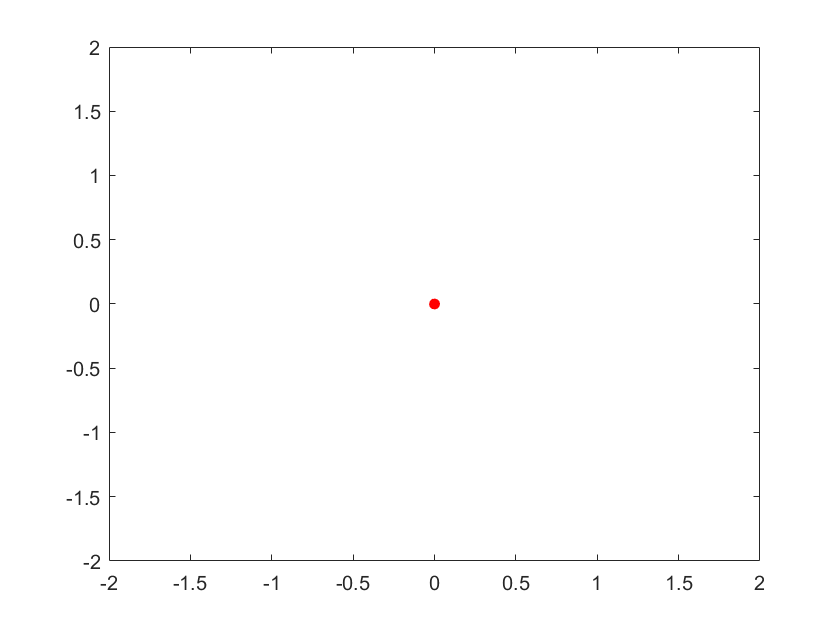

n = 20;


XY = 10 * rand(2,n) - 5;
for i=1:n
    plot(P^i*Gx.',P^i*Gy.','or','MarkerSize',5,'MarkerFaceColor','r')
    axis([-2 2 -2 2])
    pause(1)
end

A= [0 1/3 1/3;
    1/3 0 1/3;
    1/3 1/3 0]

A =          0    0.1429    0.1429
    0.1429         0    0.1429
    0.1429    0.1429         0


B= [1; 1; 1]

B =      1
     1
     1


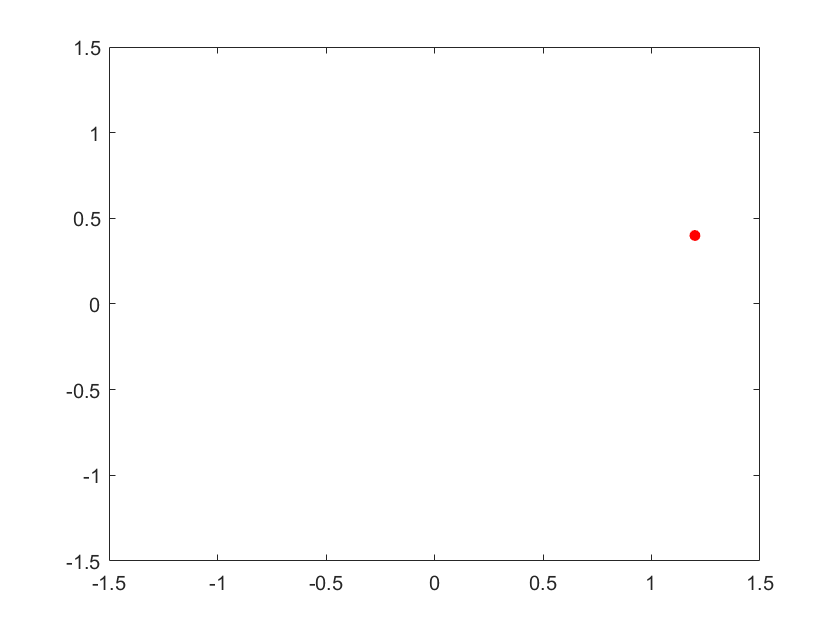

Index in position 2 exceeds array bounds (must not exceed 9).

Gx =    -3.6354
    3.8607
   -0.8409
         0


Gy =     4.6533
   -1.3058
    3.2294
         0


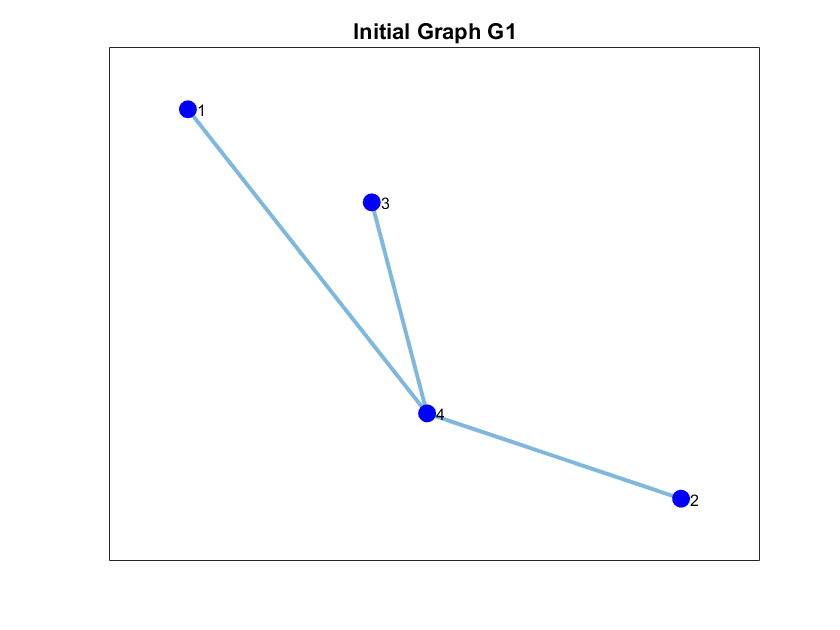

L =      3    -1    -1    -1
    -1     3    -1    -1
    -1    -1     3    -1
    -1    -1    -1     3


P =     0.5000         0         0    0.5000
         0    0.5000         0    0.5000
         0         0    0.5000    0.5000
         0         0         0    1.0000


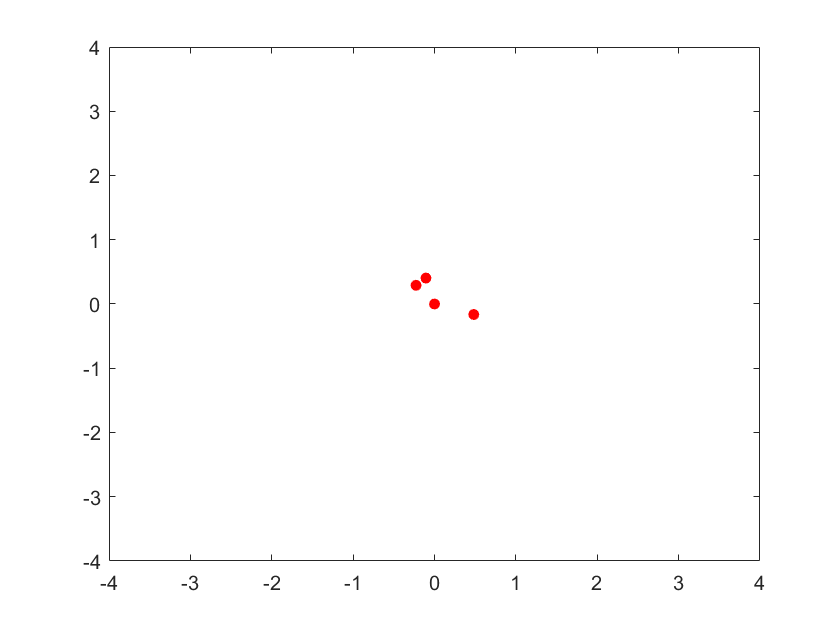

Gx_new =    -0.1136
    0.2413
   -0.0526
         0



for i=1:n
    plot([(A^i)*( Gx(:,1:3) ).'+ B*X_l(1,i); X_l(1,i)], [(A^i)*( Gy(:,1:3) ).'+ B*X_l(2,i); X_l(2,i)],'or','MarkerSize',5,'MarkerFaceColor','r')
    axis([-1.5 1.5 -1.5 1.5])
    pause(1)
end